# レギュラーシーズンのEloレーティングからプレイオフを予測する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

2018-19シーズンのチームと試合を抽出する．

seasonStartYearVal=2018;
ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);
numTeams=size(unique(tbl_teams_tmp.TeamName),1);

試合は訓練用(train)とテスト用(test)に分ける

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_train=tbl_results(ind,:);

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isPlayoff;
tbl_results_test=tbl_results(ind,:);

### 比較のために勝敗や得失点も集計する

勝，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(tbl_teams_tmp,1),1);
Loses=zeros(size(tbl_teams_tmp,1),1);
ScoresFor=zeros(size(tbl_teams_tmp,1),1);
ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

勝利数，敗北数，勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
tbl_teams_tmp=addvars(tbl_teams_tmp, Wins, Loses, WinRatio, ScoreRatio);

勝率→得失点割合の優先順でソートし，その順位を追加する

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
RankByWins=(1:size(tbl_teams_tmp,1))';
tbl_teams_tmp=addvars(tbl_teams_tmp,RankByWins);
RatingElo=1500*ones(size(tbl_teams_tmp,1),1);
tbl_teams_tmp=addvars(tbl_teams_tmp, RatingElo);

### Kを変えてEloレーティングを算出する

KVals=1:32;
isPredictionCorrectByEloK=[];
for K=KVals
    RatingElo=1500*ones(size(tbl_teams_tmp,1),1);
    for n1=1:size(tbl_results_train,1)
        homeNum= find(tbl_results_train.Home(n1) == tbl_teams_tmp.TeamName);
        awayNum= find(tbl_results_train.Away(n1) == tbl_teams_tmp.TeamName);
        homeRating= RatingElo(homeNum);
        awayRating= RatingElo(awayNum);
        p_ij=1/(1+10^(-(homeRating-awayRating)/400));
        if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
            s_ij=1;
        else
            s_ij=0;
        end
        RatingElo(homeNum)=RatingElo(homeNum)+K*(s_ij-p_ij);
        RatingElo(awayNum)=RatingElo(awayNum)-K*(s_ij-p_ij);
    end
    tbl_teams_tmp.RatingElo=RatingElo;

プレイオフの結果を予測する

予測と実際の結果を格納する変数を定義する

    PredictionByWin=zeros(size(tbl_results_test,1),1);
    PredictionByElo=zeros(size(tbl_results_test,1),1);
    ActualWin=zeros(size(tbl_results_test,1),1);
    plotData=[];
    for n1=1:size(tbl_results_test,1)
        if tbl_results_test.HomeScore(n1)>tbl_results_test.AwayScore(n1)
            ActualWin(n1)=1;    %ホーム勝利を1と定義する
        else
            ActualWin(n1)=0;
        end

        TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test.Home(n1));
        TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test.Away(n1));
        TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
        TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
        if TeamARank<TeamBRank
            PredictionByWin(n1)=1;
        else
            PredictionByWin(n1)=0;
        end

        TeamAElo=tbl_teams_tmp.RatingElo(TeamANum);
        TeamBElo=tbl_teams_tmp.RatingElo(TeamBNum);
        if TeamAElo>TeamBElo
            PredictionByElo(n1)=1;
        else
            PredictionByElo(n1)=0;
        end
    end
    isPredictionCorrectByElo= ActualWin==PredictionByElo;
    isPredictionCorrectByEloK=[isPredictionCorrectByEloK isPredictionCorrectByElo];
end

勝率に基づく予測正解を判定する．

isPredictionCorrectByWin= ActualWin==PredictionByWin;

勝率に基づく予測正解率を算出する

predictionAccuracyByWin=mean(isPredictionCorrectByWin)

predictionAccuracyByWin = 0.6951

結果と予測，予測正解かどうかを図示する

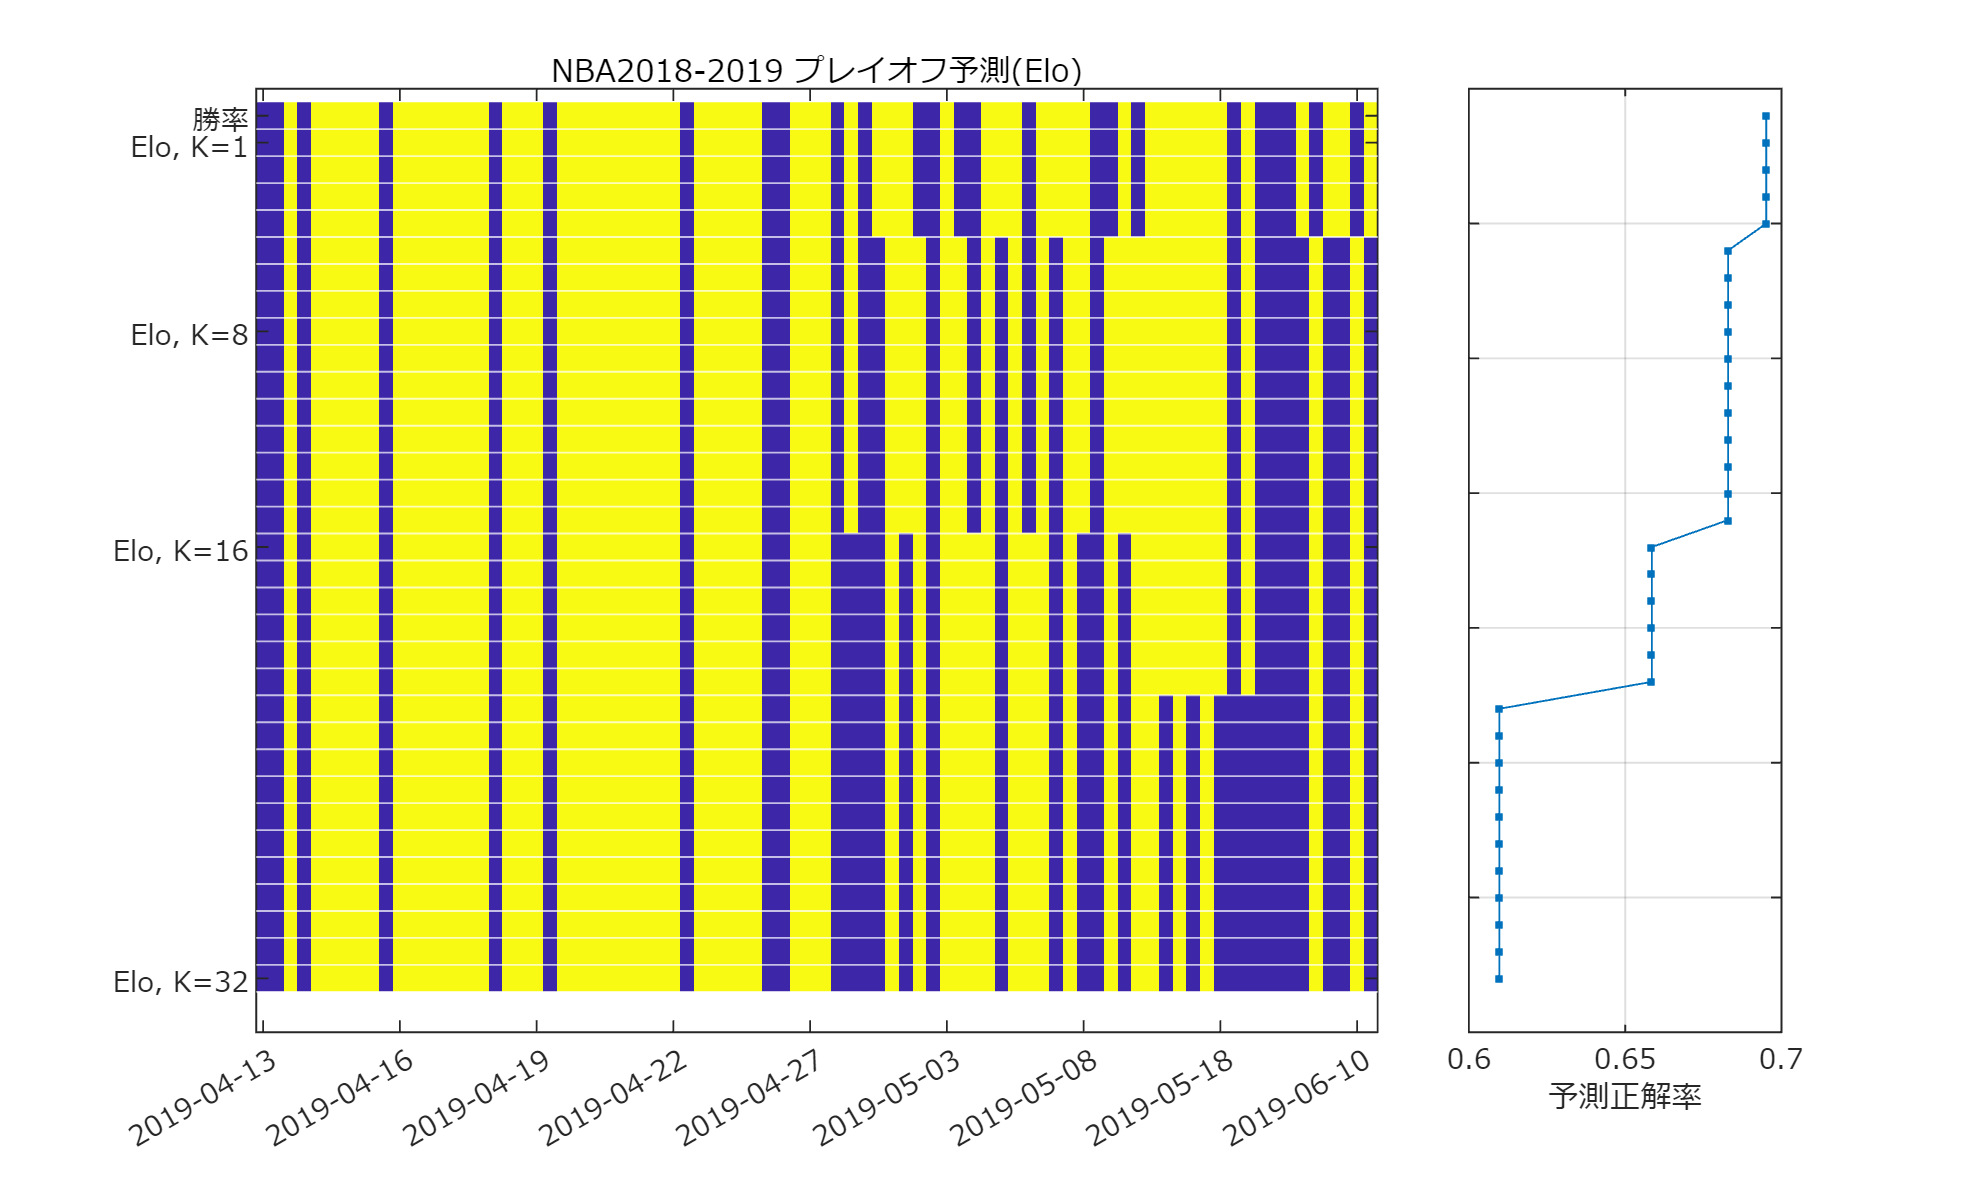

figure('Position', [100 100 560*1.25 420]);
tiledlayout(1,4);
ax1=nexttile([1,3]);
imagesc([isPredictionCorrectByWin isPredictionCorrectByEloK]');
yline(1.5:33.5,'w')
cmap=colormap(gca);
colormap(cmap([1,end],:));
set(gca,'fontname','メイリオ');
xticks(1:10:size(tbl_results_test,1));
xticklabels(string(tbl_results_test.Date(1:10:end)));
yticks([1:2, 9,17,33]);
yticklabels({'勝率','Elo, K=1','Elo, K=8','Elo, K=16','Elo, K=32'});
title('NBA2018-2019 プレイオフ予測(Elo)');
ax2=nexttile;
plotData=mean([isPredictionCorrectByWin isPredictionCorrectByEloK]);
plot(plotData, 1:size(plotData,2),'.-');grid on;
set(gca,'ydir','reverse');
yticklabels([]);
set(gca,'fontname','メイリオ');
xlabel('予測正解率')
linkaxes([ax1,ax2],'y');
exportgraphics(gcf,'fig_NBA20182019PredictionByEloK.pdf');

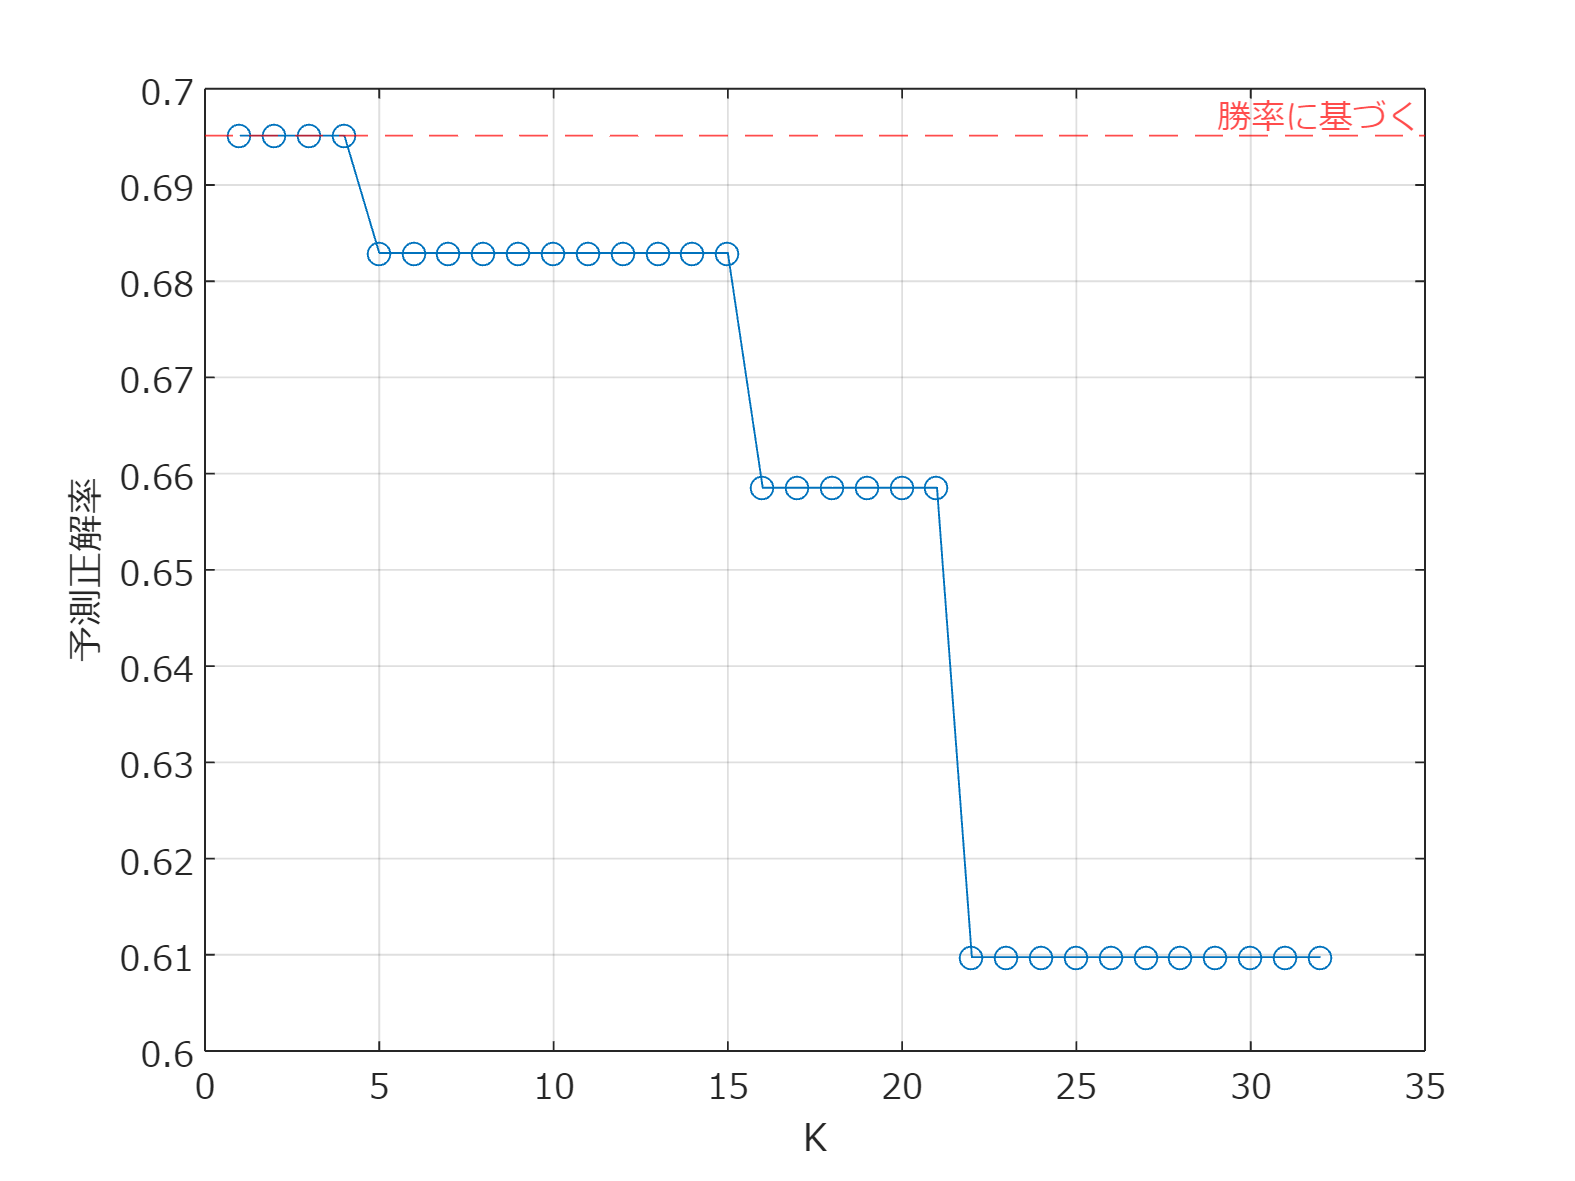

figure;
plotData=mean(isPredictionCorrectByEloK);
plot(KVals, plotData,'o-');hold on;grid on;
yline(mean(isPredictionCorrectByWin),'r--','勝率に基づく','fontname','メイリオ');
set(gca,'fontname','メイリオ');
xlabel('K');ylabel('予測正解率')
exportgraphics(gcf,'fig_NBA20182019PredictionByEloKMean.pdf');